# Single Parameter Wavelet Based Local Contrast Enhancement

**file_path: put full image path here**

**confirm if your image is loaded with 3 channels or 1. sometimes the image is grayscale but it is loaded with 3 channel. if this is the case, do not check the box**

**parameter: intensity of enhancement**

**offset: brightness added or reduced**

**CLAHE (optional)**

clear; clc; close all;

file_path = "E:\github\Image processing class and project\Course project\original_images\img20.bmp";
image_is_single_channel = false;


parameter = 2.5;

brightness = 0;

CLAHE = false;

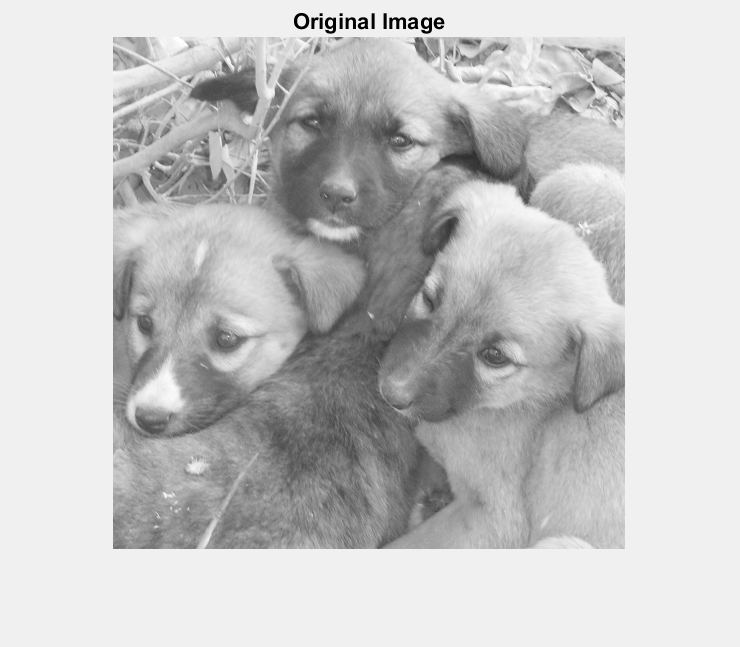

 


image_original = imread(file_path);
if ~image_is_single_channel
    image_original = rgb2gray(image_original);
end
[h, w, ~] = size(image_original);
if ~CLAHE
    image = image_original(1:h-mod(h,16), 1:w-mod(w,16), :);
else
    image = adapthisteq(image_original(1:h-mod(h,16), 1:w-mod(w,16), :));
end
image_denoised = wdenoise2(image, 'DenoisingMethod', 'SURE');

[A,H,V,D] = swt2(image_denoised,4,'haar');
cutoff = my_iswt2_extract_sigmas(A,H,V,D, 'haar');
my_sigma = cutoff./3;
g = [1 1 1 1].*[parameter parameter+1 parameter+0.5 parameter].* my_sigma .*2.5;

enhanced = my_iswt2(A,H,V,D, 'haar', my_sigma, g) + brightness;

fig1 = figure;
set(gcf,'Visible','on')
% fig1.Position(3:4) = [w, h];
imshow(uint8(image_original(1:h-mod(h,16), 1:w-mod(w,16))), [0 255])
title('Original Image')

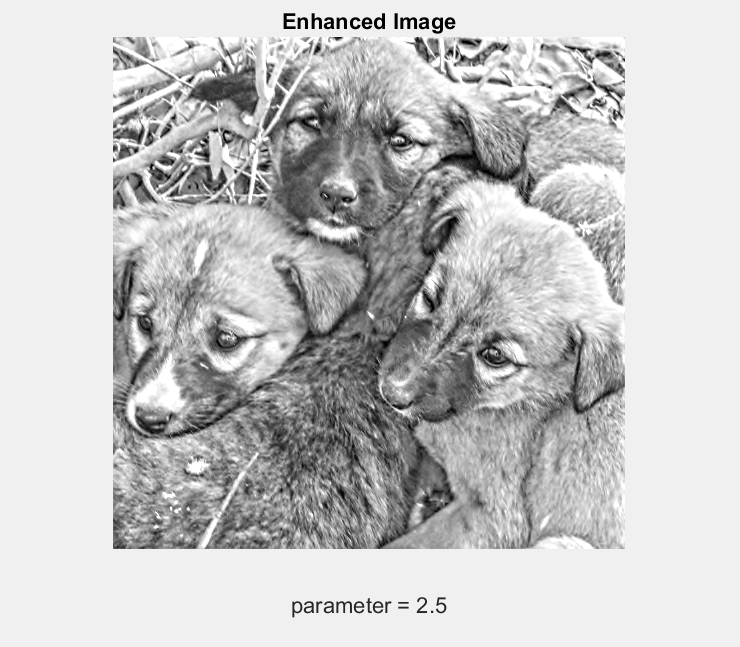


fig2 = figure;
set(gcf,'Visible','on')
% fig2.Position(3:4) = [w-mod(w,16), h-mod(h,16)];
imshow(uint8(enhanced), [0 255])
title('Enhanced Image')
xlabel(['parameter = ' num2str(parameter)])